rng(222)
xdata=1:6;
ydata=xdata+0.5*randn(1,6);

## a.

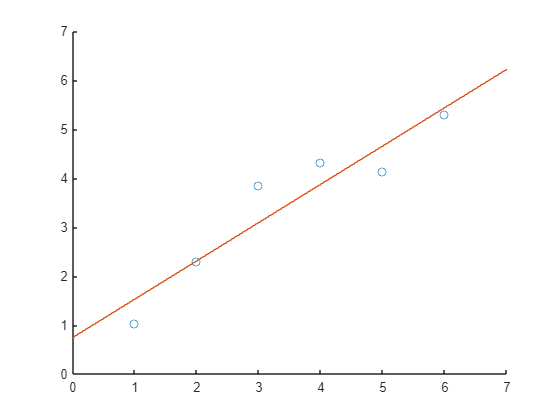


xval=0:.1:7;
p1=polyfit(xdata,ydata,1);
y1val=polyval(p1,xval);

figure 
scatter(xdata,ydata)
hold on
plot(xval,y1val)

## b.

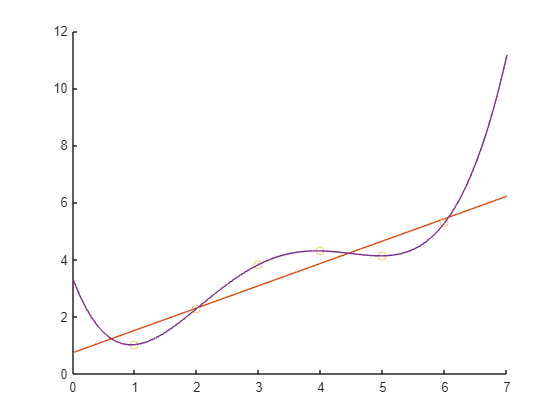

p5=polyfit(xdata,ydata,5); % only need 5th to fit 6 dots
y5val=polyval(p5,xval);
figure
scatter(xdata,ydata)
hold on 
plot(xval,y5val)

## c.

rng(12345)
xtest = 1.5:5.5 ;
ytest = xtest + 0.5*randn(1,5) ;

## d.

ypred1 = polyval(p1,xtest)

ypred1 =         1.921       2.7028       3.4845       4.2663        5.048


%% e.
ypred5 = polyval(p5,xtest)

ypred5 =        1.4716       3.1615        4.218       4.2113       4.3714


%% f.
sum((ypred1-ytest).^2)

ans =        1.0527

sum((ypred5-ytest).^2)

ans =        4.3062

% linear is prefered